# Evaluación 24 de Abril de 2026

## Santiago Patricio Gómez Ochoa | A01735171

### Ejercicio 2

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 10;             % Tiempo de simulacion (ajustado al dominio)
ts = 0.1;            
t = 0: ts: tf;       
N = length(t);       

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

% Condiciones de la trayectoria específicas
x1(1) = 0;              
y1(1) = 0;              
phi(1) = atan(2);       

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); % velocidad lineal
w = zeros(1,N); % velocidad angular

for k = 1:N
    
    tk = t(k);
    
    dx = 1;
    dy = 2*(exp(-0.3*tk)*cos(tk) - 0.3*exp(-0.3*tk)*sin(tk));
    
    % Velocidad lineal
    u(k) = sqrt(dx^2 + dy^2);
    
    expr = 2*(-0.6*exp(-0.3*tk)*cos(tk) - 0.91*exp(-0.3*tk)*sin(tk));
    % Velocidad angular
    w(k) = expr / (1 + (2*(exp(-0.3*tk)*cos(tk) - 0.3*exp(-0.3*tk)*sin(tk)))^2);
    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    %Aplicamos el modelo cinemático diferencial para obtener las
    %velocidades en x, y, phi
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k)

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

phip = -0.2400

phip = -0.2961

phip = -0.3615

phip = -0.4386

phip = -0.5301

phip = -0.6386

phip = -0.7659

phip = -0.9116

phip = -1.0704

phip = -1.2294

phip = -1.3663

phip = -1.4532

phip = -1.4673

phip = -1.4035

phip = -1.2776

phip = -1.1169

phip = -0.9470

phip = -0.7851

phip = -0.6396

phip = -0.5128

phip = -0.4035

phip = -0.3093

phip = -0.2276

phip = -0.1556

phip = -0.0913

phip = -0.0325

phip = 0.0222

phip = 0.0741

phip = 0.1242

phip = 0.1734

phip = 0.2221

phip = 0.2707

phip = 0.3193

phip = 0.3676

phip = 0.4150

phip = 0.4607

phip = 0.5034

phip = 0.5415

phip = 0.5732

phip = 0.5968

phip = 0.6108

phip = 0.6142

phip = 0.6066

phip = 0.5886

phip = 0.5611

phip = 0.5258

phip = 0.4846

phip = 0.4393

phip = 0.3916

phip = 0.3429

phip = 0.2943

phip = 0.2467

phip = 0.2007

phip = 0.1564

phip = 0.1142

phip = 0.0740

phip = 0.0360

phip = 9.4740e-05

phip = -0.0337

phip = -0.0655

phip = -0.0951

phip = -0.1225

phip = -0.1477

phip = -0.1705

phip = -0.1908

phip = -0.2084

phip = -0.2232

phip = -0.2351

phip = -0.2440

phip = -0.2498

phip = -0.2525

phip = -0.2522

phip = -0.2490

phip = -0.2430

phip = -0.2345

phip = -0.2237

phip = -0.2110

phip = -0.1966

phip = -0.1809

phip = -0.1641

phip = -0.1466

phip = -0.1285

phip = -0.1103

phip = -0.0920

phip = -0.0739

phip = -0.0561

phip = -0.0388

phip = -0.0222

phip = -0.0064

phip = 0.0086

phip = 0.0226

phip = 0.0356

phip = 0.0475

phip = 0.0583

phip = 0.0678

phip = 0.0762

phip = 0.0832

phip = 0.0890

phip = 0.0936

phip = 0.0969

phip = 0.0990

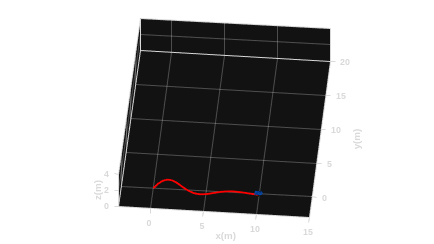


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([5 40]); % Orientacion de la figura
axis([-3 15 -3 20 0 4]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

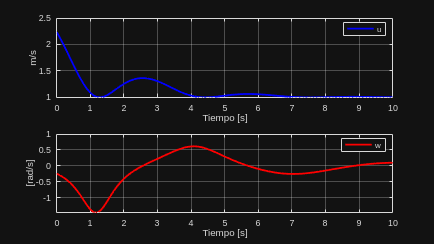


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

### Ejercicio 2

clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 15;             
ts = 0.1;            
t = 0: ts: tf;       
N = length(t);       

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

x1(1) = 0;              
y1(1) = 0;              
phi(1) = atan(0);             

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); 
w = zeros(1,N); 

for k = 1:N
    
    tk = t(k);
    
    % -------- TRAMO 1 --------
    % % %Función y(t)= 0.5x^2
    % t=[0 <= x < 3]

    if 0 <= tk && tk < 3
        
        dx = 1;
        dy = tk;
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = 1 / (1 + (tk)^2);
        
            
        % -------- TRAMO 2 --------
        %Función y(t)= -(x-5)^2 + 8
        % t=[3 <= x < 7]
        
    elseif 3 <= tk && tk < 7
        
        dx = 1;
        dy = -2*tk +10;

        u(k) = sqrt(dx^2 + dy^2);
        num = -2
        den = 1 + (-2*tk +10)^2
        w(k) = num / den;
        
            
        % -------- TRAMO 3 --------
        %Función y(t)=2e^(x-t)cos(x-7)
        % t=[7 <= x <= 10]
        
    elseif 7 <= tk && tk <= 10
        
        dx = 1;
        dy = 2*exp(tk-7).*(cos(tk-7) - sin(tk-7));
        
        u(k) = sqrt(dx^2 + dy^2);

        num = -4*exp(tk-7).*sin(tk-7);
        den = 1 + dy^2;
        w(k) = num / den;
        
    end
    
end

num = -2

den = 17

num = -2

den = 15.4400

num = -2

den = 13.9600

num = -2

den = 12.5600

num = -2

den = 11.2400

num = -2

den = 10

num = -2

den = 8.8400

num = -2

den = 7.7600

num = -2

den = 6.7600

num = -2

den = 5.8400

num = -2

den = 5

num = -2

den = 4.2400

num = -2

den = 3.5600

num = -2

den = 2.9600

num = -2

den = 2.4400

num = -2

den = 2

num = -2

den = 1.6400

num = -2

den = 1.3600

num = -2

den = 1.1600

num = -2

den = 1.0400

num = -2

den = 1

num = -2

den = 1.0400

num = -2

den = 1.1600

num = -2

den = 1.3600

num = -2

den = 1.6400

num = -2

den = 2

num = -2

den = 2.4400

num = -2

den = 2.9600

num = -2

den = 3.5600

num = -2

den = 4.2400

num = -2

den = 5

num = -2

den = 5.8400

num = -2

den = 6.7600

num = -2

den = 7.7600

num = -2

den = 8.8400

num = -2

den = 10

num = -2

den = 11.2400

num = -2

den = 12.5600

num = -2

den = 13.9600

num = -2

den = 15.4400

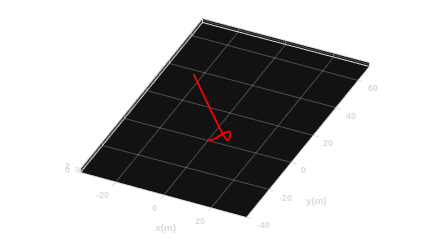


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts;
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts; 
    y1(k+1)=y1(k) + yp1*ts; 
    
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');

view([25 35]);
axis([-35 35 -40 70 0 2]);

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

step=1;

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

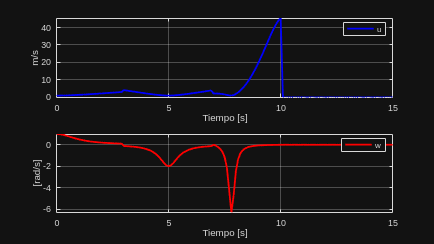


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph=figure;
set(graph,'position',sizeScreen);

subplot(211)
plot(t,u,'b','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('m/s'),legend('u')

subplot(212)
plot(t,w,'r','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w')